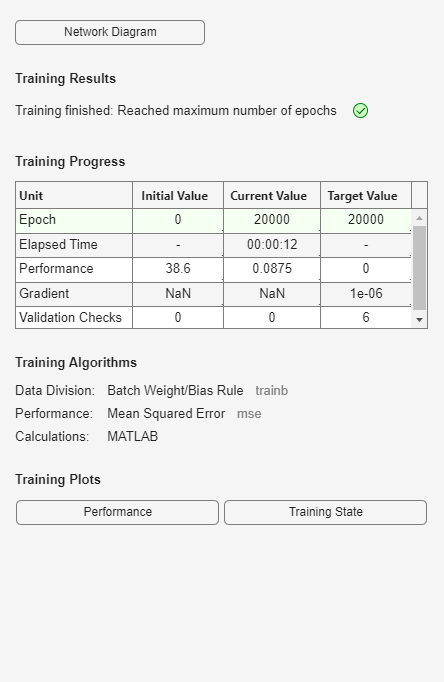

%ÏßÐÔÍøÂç¡ª¡ª¶àÊäÈë-µ¥Êä³ö£¨½»Í¨ÔËÊäÒµµÄÓ°ÏìÒòËØ£©
clear                                       %ÇåÀíÄÚ´æ
X=[57.82 58.05 59.15 63.83 65.36 67.26 66.92 67.79 75.65 80.57 79.02 80.52 86.88 95.48 109.71 126.5 138.89 160.56
27.05 28.89	33.02 35.23	24.94 32.95	30.35 38.7 47.99 54.18 58.73 59.85 64.57 70.97 81.54 94.01 103.23 119.33
14.54 16.83	12.26 12.87	11.65 12.87	10.8 10.93 14.71 17.56 20.32 18.67 25.34 25.06 29.69 43.86 48.9	60.98];
y=[3.09	3.4	3.88 3.9 3.22 3.76 3.59	4.03 4.34 4.65 4.78	5.04 5.59 6.01 7.03	10.03 10.83	12.9];
P=X/40;                                     %ÊäÈë±äÁ¿È«²¿³ýÒÔ40
T=y;                                        %Êä³ö±äÁ¿²»±ä
net=newlin(minmax(P),1,0,0.01);             %¹¹½¨Ò»¸öµ¥Êä³öÏßÐÔÍøÂç
net.trainParam.epochs=20000;                %Ö¸¶¨×î´óÑµÁ·´ÎÊý
net=train(net,P,T);                         %ÍøÂçÑµÁ·

Y=sim(net,P)                                %·ÂÕæ²¢Êä³ö½á¹û

Y =     3.4046    3.6176    3.2474    3.5528    3.5681    3.7517    3.5556    3.5820    4.3223    4.8282    4.9744    4.9033    5.8411    6.2658    7.4306    9.5945   10.7001   12.9299


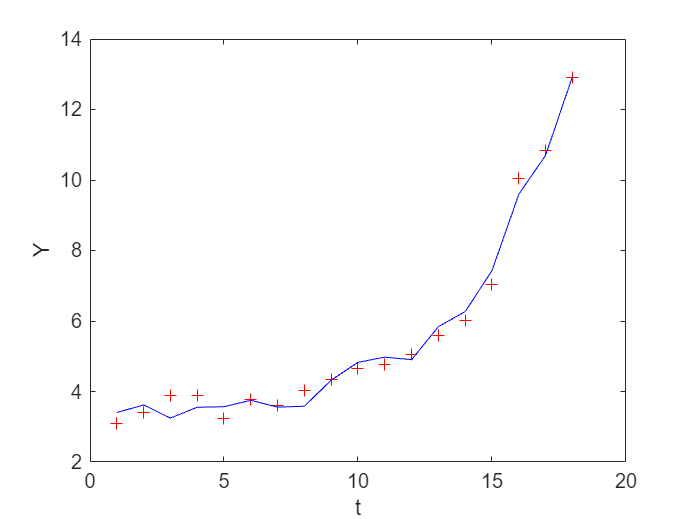

figure;                                     %±£ÁôÎó²îÇúÏßÍ¼
t=1:length(Y);                              %¶¨ÒåÊ±Ðò
plot(t,T,'r+');                             %»æÖÆÊä³ö±äÁ¿É¢µãÍ¼
xlabel('t');                                %ºáÖá±êÇ©£¨Ê±Ðò£©
ylabel('Y');                                %×ÝÖá±êÇ©£¨ÔËÊäÒµ²úÖµ£©
hold on                                     %±£³ÖÍ¼ÐÎ
plot(t,Y,'b-');                             %ÔÚÉ¢µãÍ¼ÖÐÌí¼Ó·ÂÕæÇúÏß
hold off                                    %½áÊø»æÍ¼

w=net.iw{1,1}                               %Êä³öÈ¨ÊýÏòÁ¿

w =     2.2130   -0.1607    3.6278


b=net.b{1}                                  %Êä³öãÐÖµ

b = -1.0044